cc = ColorConversionClass;
cie2 = CMF_CIE_2deg;
cie10 = CMF_CIE_10deg;

figure
hold

Current plot held


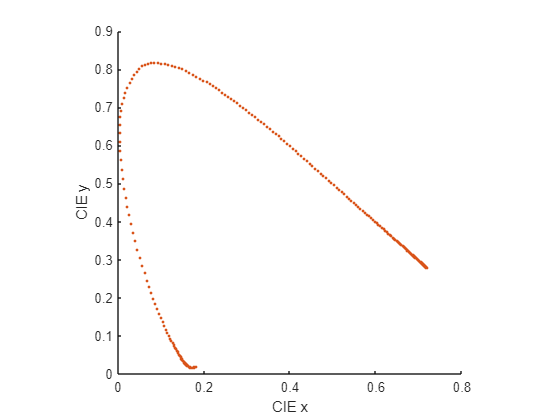

cie10.show_spectral_locus
cie10.show_spectral_locus_official

%axis([0.15 0.2 0 0.05])

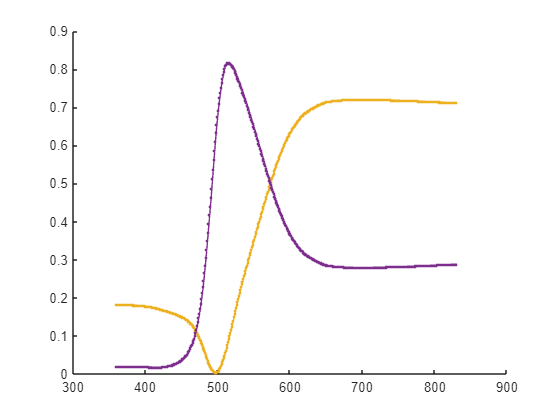

figure
hold on
cie10.plot_spectral_locus_xy()
cie10.plot_spectral_locus_xy_official()

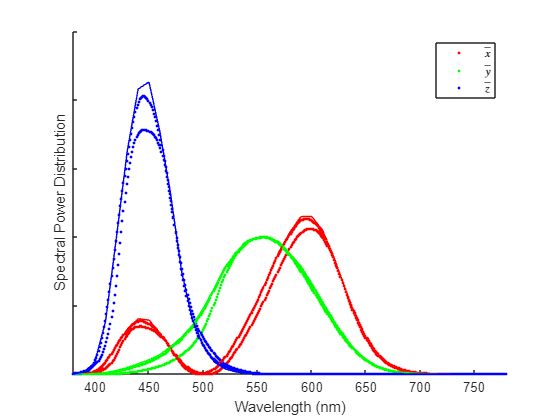

figure
cie2.show_color_matching_functions
cie10.show_color_matching_functions
cc.show_color_matching_functions_raw


figure
cie10.show_color_matching_functions
cc.show_color_matching_functions_raw

cc = ColorConversionClass;

%
% create single-spike spectra between [380:10:780]
%
n = 41;                                                          %  ColorConversionClass.spd2XYZ accepts 41 bands only
data41_x_y = zeros(n,2);
for w = 1:41
    sp = zeros(n,1);
    sp(w) = 100000;
    XYZ = cc.spd2XYZ(sp);
    xyz = XYZ ./ sum(XYZ);
    data41_x_y(w,:) = xyz(1:2);
end

data401_x_y = zeros(401,2);
data401_x_y(:,1) = interp1(380:10:780,data41_x_y(:,1),380:780,'spline');
data401_x_y(:,2) = interp1(380:10:780,data41_x_y(:,2),380:780,'spline');


for w = 1
    sp = zeros(n,1);
    sp(w) = 100000;
    sp
    XYZ = cc.spd2XYZ(sp)
    xyz = XYZ ./ sum(XYZ)
end

figure
hold on
cmf = cc.cmf_1964;
itv = 1:5;
plot(cmf(itv,1),cmf(itv,2),'-o')
plot(cmf(itv,1),cmf(itv,3),'-o')
plot(cmf(itv,1),cmf(itv,4),'-o')

figure
plot(data41_x_y,'-o')
legend

figure
hold on 

plot(data401_x_y(:,1),data401_x_y(:,2),'-')
axis equal
%axis([0.15 0.2 0 0.05])

% https://cie.co.at/datatable/cie-1931-chromaticity-coordinates-spectrum-loci-2-degree-observer
% https://cie.co.at/datatable/cie-1964-chromaticity-coordinates-spectrum-loci-10-degree-observer
cmf = cmf10deg;
plot(cmf(:,2),cmf(:,3),'-')



cmf_x = cmf(:,2) ./ sum(cmf(:,2:4),2);
cmf_y = cmf(:,3) ./ sum(cmf(:,2:4),2);

hold on
plot(cmf_x,cmf_y,'-')
axis equal
%axis([0.15 0.2 0 0.05])
axis([0 1 0 1])

cmf = cmf10deg;
cmf_x = cmf(:,2) ./ sum(cmf(:,2:4),2);
cmf_y = cmf(:,3) ./ sum(cmf(:,2:4),2);


hold on
plot(cmf_x,cmf_y,'-')
axis equal
%axis([0.15 0.2 0 0.05])
axis([0 1 0 1])

legend('My','CIE2','CIE10')

figure
hold on
cmf = cc.cmf_1964;
itv = 1:41;
plot(cmf(itv,1),cmf(itv,2),'-o')
plot(cmf(itv,1),cmf(itv,3),'-o')
plot(cmf(itv,1),cmf(itv,4),'-o')

cmf = cmf2deg;
itv = 1:471;
plot(cmf(itv,1),cmf(itv,2),'-')
plot(cmf(itv,1),cmf(itv,3),'-')
plot(cmf(itv,1),cmf(itv,4),'-')

figure
itv = 1:100;
plot(data401_x_y(itv,:),'-o')


% add the purple line between the first and last points of the
% spectral locus
xy1 = data401_x_y(1,:);
xy2 = data401_x_y(end,:);
pl_x = linspace(xy1(1),xy2(1),200)';
pl_y = linspace(xy1(2),xy2(2),200)';
pl_xy = [pl_x pl_y];

% data401_x_y = [data401_x_y ; pl_xy];


